# Stepwise Linear Model Study

See Fama and French, 1993, "Common Risk Factors in the Returns on Stocks and Bonds," *Journal of Financial Economics*

**The Fama/French factors are constructed using the 6 value-weight portfolios formed on size and book-to-market.**

***[Factor #1: ****Market****] ****ri = rf + Beta*(rm - rf)*

SMB (Small Minus Big) is the average return on the three small portfolios minus the average return on the three big portfolios,

***[Factor #2: ****Size****] SMB**** = 1/3 (Small Value + Small Neutral + Small Growth) - 1/3 (Big Value + Big Neutral + Big Growth). *

HML (High Minus Low) is the average return on the two value portfolios minus the average return on the two growth portfolios,

***[Factor #3: ****Value vs. Growth****] HML**** =1/2 (Small Value + Big Value) - 1/2 (Small Growth + Big Growth).*

Rm-Rf, the excess return on the market, value-weight return of all CRSP firms incorporated in the US and listed on the NYSE, AMEX, or NASDAQ that have a CRSP share code of 10 or 11 at the beginning of month t, good shares and price data at the beginning of t, and good return data for t minus the one-month Treasury bill rate (from Ibbotson Associates).

***[Factor #4:**** Momentum****]*** ***UMD = ****Up-Minus-Down = Top 50% of highest performing stocks in the last 12 months - Bottom 50% of lowest performing stocks in the last 12 months*

***Data reference:***

- [https://mba.tuck.dartmouth.edu/pages/faculty/ken.french/data_library.html](https://mba.tuck.dartmouth.edu/pages/faculty/ken.french/data_library.html)

- [https://finance.yahoo.com/quote](https://finance.yahoo.com/quote)

**Columbia University - Machine Learning for Enterprise Risk Management**                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                 [malphons@mathworks.com](http://malphons@mathworks.com) **|** [https://www.linkedin.com/in/marshallalphonso](https://www.linkedin.com/in/marshallalphonso)

### Load in Equity Data

load FF4Data.mat
holdoutPCT = 0.2;
retSecurity = E.smallReturns.ABG;
[T,Ttrain,Ttest] = getCrossValFactorData(retSecurity,FF4,holdoutPCT);

### Linear Model


$$y=\beta_1 *\textrm{Fm}+\beta_2 *\textrm{Fhml}+\beta_3 *\textrm{Fsmb}+\beta_4 *\textrm{Fmom}\;\;$$


MdlLinear = fitlm(Ttrain,'rSec_Minus_rRiskFree ~ rMkt_Minus_rRiskFree + rSizeFactor + rValueGrowthFactor + rMomentum')

MdlLinear = Linear regression model:
    rSec_Minus_rRiskFree ~ 1 + rMkt_Minus_rRiskFree + rSizeFactor + rValueGrowthFactor + rMomentum

Estimated Coefficients:
                            Estimate        SE         tStat      pValue  
                            _________    _________    _______    _________

    (Intercept)             0.0071447    0.0056248     1.2702      0.20528
    rMkt_Minus_rRiskFree       1.7334      0.16155      10.73    4.511e-22
    rSizeFactor                1.6272      0.51265     3.1742    0.0017062
    rValueGrowthFactor        0.86699      0.51588     1.6806     0.094185
    rMomentum                 0.32399      0.69939    0.46325      0.64362


Number of observations: 237, Error degrees of freedom: 232
Root Mean Squared Error: 0.0822

### StepWise Model


$$y=\beta_1 *\textrm{Fi}\;$$


yLinear = predict(MdlLinear,Ttest);

MdlStepwise = stepwiselm(Ttrain,'linear')

1. Removing rValueGrowthFactor, FStat = 0.06978, pValue = 0.79189
2. Removing rSec_Minus_rRiskFree, FStat = 0.19174, pValue = 0.66187


MdlStepwise = Linear regression model:
    rMomentum ~ 1 + rMkt_Minus_rRiskFree + rSizeFactor

Estimated Coefficients:
                            Estimate         SE        tStat       pValue  
                            _________    __________    ______    __________

    (Intercept)             0.0014166    0.00051648    2.7429     0.0065614
    rMkt_Minus_rRiskFree     0.076114       0.01384    5.4996     9.948e-08
    rSizeFactor               0.23684      0.043936    5.3906    1.7128e-07


Number of observations: 237, Error degrees of freedom: 234
Root Mean Squared Error: 0.00768
R-squared: 0.224,  Adjusted R-Squared: 0.218
F-statistic vs. constant model: 33.8, p-value = 1.27e-13

yStepwise = predict(MdlStepwise,Ttest);

MdlActual = fitlm(Ttest,'rSec_Minus_rRiskFree ~ rMkt_Minus_rRiskFree + rSizeFactor + rValueGrowthFactor + rMomentum')

MdlActual = Linear regression model:
    rSec_Minus_rRiskFree ~ 1 + rMkt_Minus_rRiskFree + rSizeFactor + rValueGrowthFactor + rMomentum

Estimated Coefficients:
                            Estimate        SE        tStat       pValue  
                            _________    ________    _______    __________

    (Intercept)             0.0099472    0.010167    0.97842       0.33231
    rMkt_Minus_rRiskFree       1.4952     0.39168     3.8174    0.00035489
    rSizeFactor                2.9884     0.89213     3.3497      0.001496
    rValueGrowthFactor        -1.1765     0.86736    -1.3564       0.18074
    rMomentum                 -1.4972      1.2945    -1.1566       0.25262


Number of observations: 58, Error degrees of freedom: 53
Root Mean Squared Error: 0.0747
R

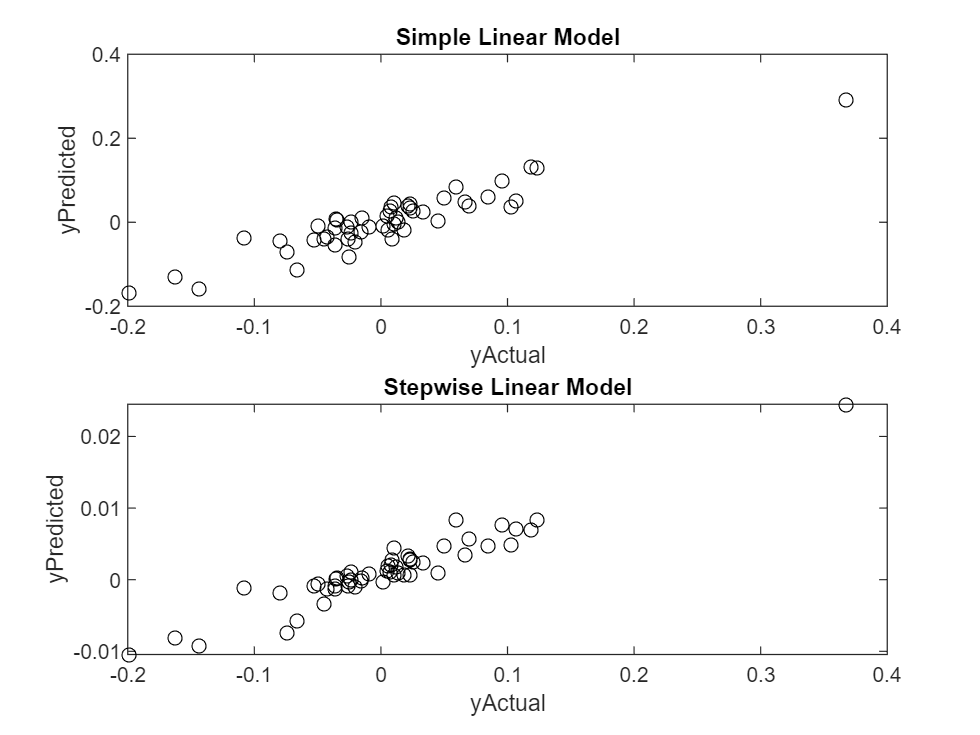

yFitActual = predict(MdlActual,Ttest);

figure
subplot(2,1,1)
plot(yFitActual,yLinear,'ko')
title('Simple Linear Model')
xlabel('yActual')
ylabel('yPredicted')
subplot(2,1,2)
plot(yFitActual,yStepwise,'ko')
title('Stepwise Linear Model')
xlabel('yActual')
ylabel('yPredicted')